# Robot Arm Visualization

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

The robot arm has four parameters. It has lengths `L1` and `L2` for the two links, and angles of rotation `theta1` and `theta2` for the two joints.

syms L1 L2 theta1 theta2

## Task 2

The *x* and *y* coordinates of the end effector can be found using the following formulas:

*x*=*L*2cos(*θ*1+*θ*2)+*L*1cos(*θ*1)

*y*=*L*2sin(*θ*1+*θ*2)+*L*1sin(*θ*1)

x = L2*cos(theta1 + theta2) + L1*cos(theta1)

$$x = L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)$$

y = L2*sin(theta1 + theta2) + L1*sin(theta1)

$$y = L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)$$

## Task 3

This robot's first link is 4 feet long and second link is 2 feet long. Substituting these values reduces the formulas from four parameters to two parameters.

To visualize the possible positions of the end effector, you can create symbolic functions which depend on the two remaining parameters, *θ*1 and *θ*2

fx(theta1, theta2) = subs(x, [L1 L2], [4 2])

$$fx(theta1, theta2) = 2\,\cos\left(\theta_{1}+\theta_{2}\right)+4\,\cos\left(\theta_{1}\right)$$

fy(theta1, theta2) = subs(y, [L1 L2], [4 2])

$$fy(theta1, theta2) = 2\,\sin\left(\theta_{1}+\theta_{2}\right)+4\,\sin\left(\theta_{1}\right)$$

## Task 4

The function `fplot` can visualize a curve using two functions, one for the *x* coordinate and one for the *y* coordinate.

`fplot``(``xFunction``,``yFunction``)`

The functions for the coordinates can only have one independent variable. If they have two independent variables, call the functions with one variable set to a constant.

`f1``(``u``,``v``)` `=` `u` `+` `v``;`

`f2``(``u``,``v``)` `=` `u``^``2` `-` `v``^``2``;`

`fplot``(``f1``(``5``,``v``)``,``f2``(``5``,``v``))`

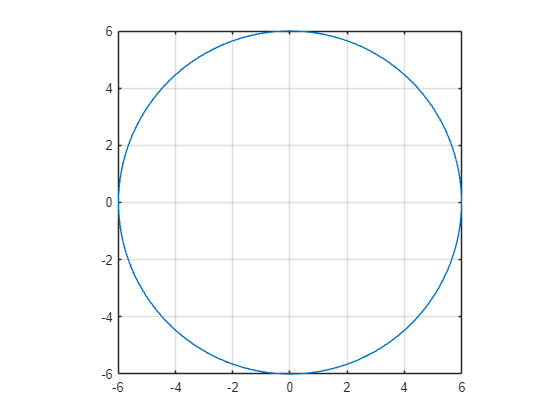

fplot(fx(theta1, 0), fy(theta1, 0))
grid on
axis equal

## Task 5

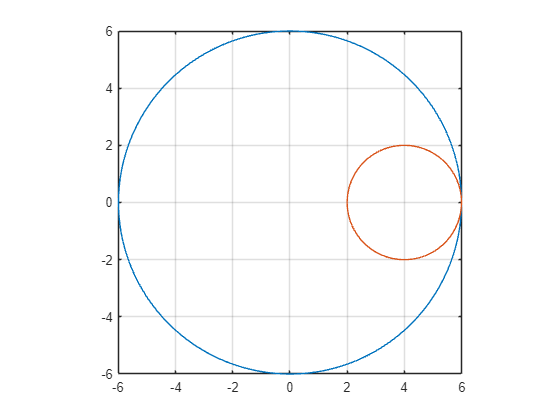

hold on
fplot(fx(0, theta2), fy(0, theta2))
grid on
hold off

## Task 6

The `fsurf` function can visualize a surface using functions for the *x*, *y*, and *z* coordinates.

`fsurf``(``xFunction``,``yFunction``,``zFunction``)`

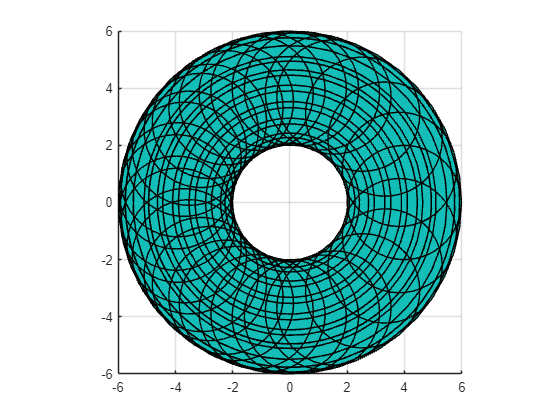

fsurf(fx, fy, 0)
view(2)
axis equal